## Quiz 5 Practice : Numerical Integration Practice

1) (50%) For the function:


$$\frac{d^2 w}{{\textrm{dx}}^2 }={3x}^2 +4\;,\frac{\textrm{dw}\left(0\right)}{\textrm{dx}}=0,w\left(0\right)=1$$
 

a) (10%) Write the above differential equation as a state system and it's derivative.

Find how many state variables you need and take the derivative of the state system


$$\begin{array}{l}
s=\left\lbrack \begin{array}{c}
w\\
\frac{dw}{dx}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack \\
s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{dw}{dx}\\
\frac{d^2 w}{{\mathrm{dx}}^2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
?
\end{array}\right\rbrack 
\end{array}$$


Find what $\frac{d^2 w}{{\textrm{dx}}^2 }$ is in terms of original state variables


$$\frac{d^2 w}{{\textrm{dx}}^2 }={3x}^2 +4$$



$${s_2 }^{\prime } =3x^2 +4$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
3{s_2 }^2 +4
\end{array}\right\rbrack$$


So we now have our system of ODEs 


$$\frac{{ds}_1 }{dx}=s_2$$



$$\frac{{\textrm{ds}}_2 }{\textrm{dx}}=3{s_2 }^2 +4$$


b) (20%) Solve the above differential equation using MATLAB's built-in ODE solver (ODE45).

clear; clc; close all;
% Set up variables for time span and initial conditions
xspan = [0 5]; % Time range for the solution
s0 = [1; 0]; % Initial conditions: w(0) = 1, dw/dx(0) = 0
% Define the system of ODEs as a function handle
f = @(x, s) [s(2); ... % ds1/dx = s2 (first derivative)
             3*x^2 + 4]; % ds2/dx = 3*x^2 + 4 (second derivative)
% Solve the ODE using ode45
[t, s] = ode45(f, xspan, s0);

c) (20%)  Plot the result for $w\left(x\right)$ for x=0 to 5 from (b). Find the analytical solution using the Symbolic Toolbox and plot it alongside the previous result as well.

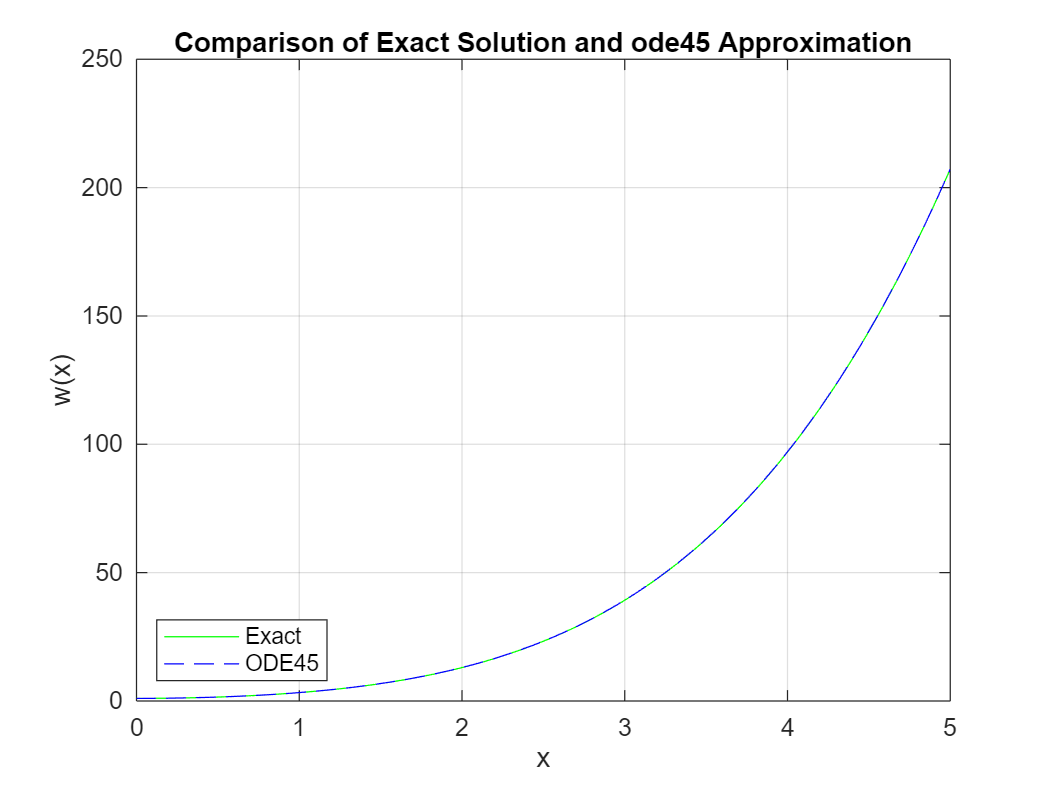

% Analytical solution using symbolic math
syms wa(xa); 
eqn = diff(wa, xa, 2) == 3*xa^2 + 4; % ODE to solve
Dwa = diff(wa, xa);
cond = [wa(0) == 1, Dwa(0) == 0]; % Initial conditions
wSol(xa) = dsolve(eqn, cond);

% Plot the analytical and numerical solutions
figure;
xx = linspace(0, 5); % Time vector for a smooth plot of the exact solution
plot(xx, wSol(xx), 'g'); % Plot exact solution
hold on;
plot(t, s(:, 1), '--b'); % Plot numerical solution
hold off;

% Add labels, legend, and title
ylabel('w(x)');
xlabel('x');
title('Comparison of Exact Solution and ode45 Approximation');
legend('Exact','ODE45', 'Location', 'southwest');
grid on; % Add grid for better visualization

2) (50%) A drug affects the body in this inclusive way when starting a 20 mg pill.


$$\frac{\textrm{dx}}{\textrm{dt}}=-0\ldotp 090x\left(t\right)+0\ldotp 028y\left(t\right)-0\ldotp 007z\left(t\right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=\;\;\;\;0\ldotp 066x\left(t\right)-0\ldotp 038y\left(t\right)-0\ldotp 021z\left(t\right)$$



$$\frac{\textrm{dz}}{\textrm{dt}}=\;\;\;\;0\ldotp 060x\left(t\right)-0\ldotp 008y\left(t\right)-0\ldotp 01z\left(t\right)$$


Where x is the amount in the blood, y is the amount in the stomach and z is the amount in the body. We assume the blood and body are empty of the drug initially.

a) (10%) Write the above differential equations as a state system and its derivative.


$$s=\left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } \\
{s_3 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } \\
z^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-0\ldotp 090s_1 +0\ldotp 028s_2 -0\ldotp 007s_3 \\
0\ldotp 066s_1 -0\ldotp 038s_2 -0\ldotp 021s_3 \\
0\ldotp 060s_1 -0\ldotp 008s_2 -0\ldotp 01s_3 
\end{array}\right\rbrack$$


b) (20%) Solve and plot the interaction over 150 minutes using MATLAB's built in ODE Solver (ODE45).

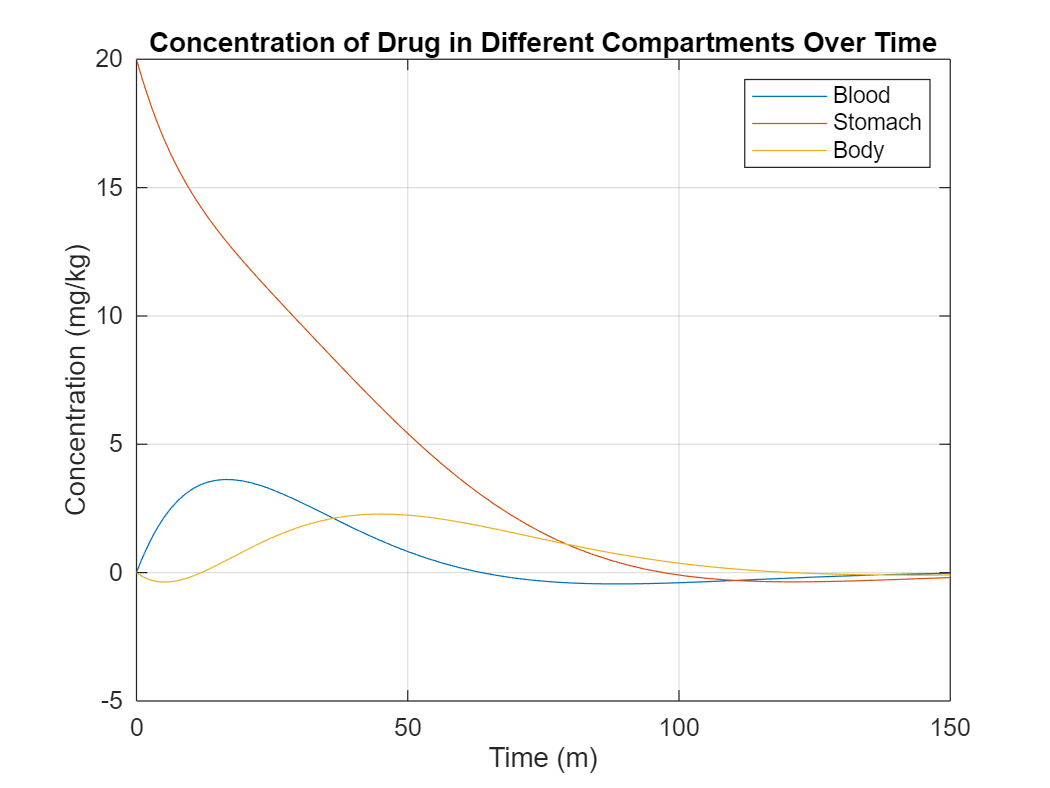

clear; clc; close all;

% Set up variables
xspan = [0 150]; % Time range for the solution
initialConditions = [0; 20; 0]; % Initial concentrations in Blood, Stomach, Body

% Set up the system of equations as a function handle
f = @(t, s) [-0.090*s(1) + 0.028*s(2) - 0.070*s(3); ... % Rate equation for Blood
             0.066*s(1) - 0.038*s(2) - 0.021*s(3); ... % Rate equation for Stomach
             0.060*s(1) - 0.008*s(2) - 0.010*s(3)];    % Rate equation for Body

% Use ode45 to solve the system of ODEs
[t, s] = ode45(f, xspan, initialConditions);

% Plot results
figure;
plot(t, s);
xlabel('Time (m)');
ylabel('Concentration (mg/kg)');
title('Concentration of Drug in Different Compartments Over Time');
legend('Blood', 'Stomach', 'Body', 'Location', 'northeast');
grid on; % Add grid for better visualization

c) (20%) Find the time point for maximum amount of drug in the blood.

[maxConcentrationBlood, maxConcentrationBloodtimeInt] = max(s(:,1));
disp(['Maximum concentration in Blood at t=: ', num2str(t(maxConcentrationBloodtimeInt)), ' m']);

Maximum concentration in Blood at t=: 16.2657 m


disp(['Maximum concentration in Blood: ', num2str(maxConcentrationBlood), ' mg/kg']);

Maximum concentration in Blood: 3.6284 mg/kg
